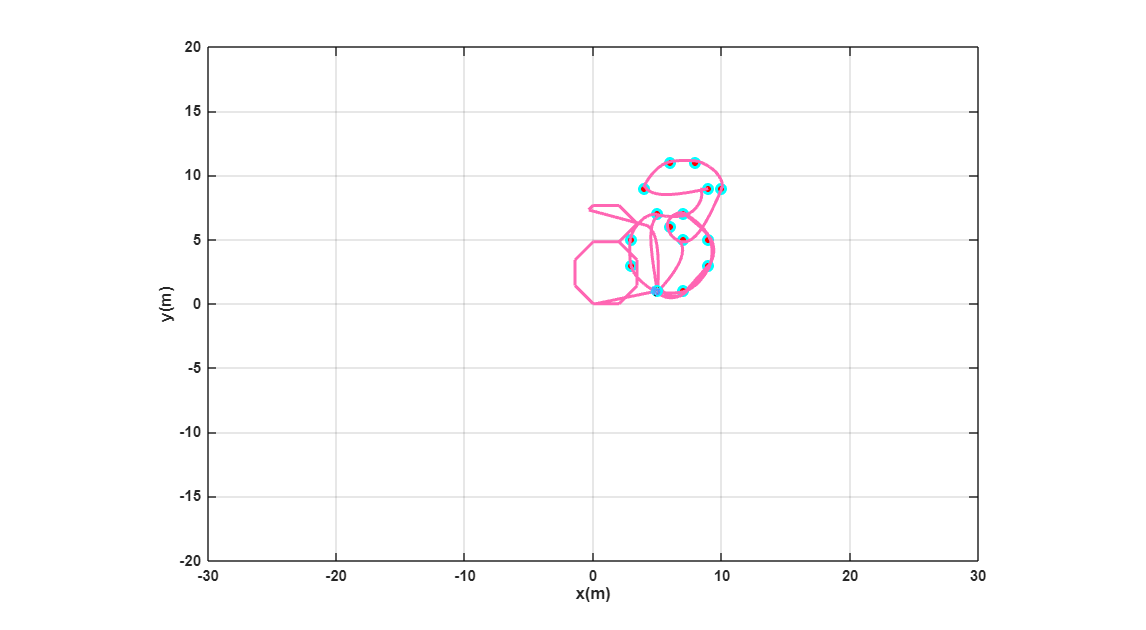

% ========================
% Condiciones iniciales
% ========================
x1(1) = 5;             % Posición inicial del robot en el eje X
y1(1) = 1;           % Posición inicial del robot en el eje Y
phi(1) = pi/2;          % Orientación inicial del robot (90°, apunta hacia arriba)
hx(1) = x1(1);          % Inicialización del historial de trayectoria en X
hy(1) = y1(1);          % Inicialización del historial de trayectoria en Y

% ========================
% Coordenadas objetivo
% ========================
coord = [5,1; 
            7,1; 
            9,3; 
            9,5; 
            7,7; 
            6,6; 
            7,5; 
            10,9;
            8,11; 
            6,11; 
            4,9; 
            9,9;
            7,7; 
            5,7; 
            3,5; 
            3,3;
            5,1];

% ========================
% Parámetros de simulación
% ========================
ts = 0.1;               % Tiempo de muestreo [s]
tf = 15;                % Tiempo final por cada objetivo [s]
N = tf / ts;            % Número de pasos por objetivo
t = linspace(0, ts, N); % Vector de tiempo para interpolación (no se usa directamente)

% ========================
% Visualización 2D del recorrido
% ========================
scale = 4;                             % Escala del robot para la visualización
sizeScreen = get(0,'ScreenSize');      % Tamaño de pantalla
scene = figure('Name','Animación trayectoria completa');  % Crear figura
set(scene, 'Color','white', 'position', sizeScreen);      % Configuración de la figura
set(gca,'FontWeight','bold');
camlight('headlight');                 % Luz de cámara
axis equal;                            % Ejes con misma escala
grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([0 90]);                          % Vista cenital (2D)
axis([-30 30 -20 20 0 1]);             % Límites de visualización

% ========================
% Mostrar puntos deseados
% ========================
hold on;
plot(coord(:,1), coord(:,2), 'ro', 'MarkerFaceColor', 'r'); % Dibujar los puntos de destino

% ========================
% Inicialización del trazado del robot
% ========================
MobileRobot_5;                 % Carga la geometría 3D del robot (script externo)
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;  % Dibujar robot en posición inicial
H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2); % Trayectoria inicial
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2);             % Punto de inicio en verde

% ========================
% Inicialización de variables de control
% ========================
v = zeros(1,N);             % Velocidad lineal del robot
w = zeros(1,N);             % Velocidad angular del robot
Error = zeros(1,N);         % Vector para almacenar errores

% ========================
% Bucle sobre cada punto objetivo
% ========================
for i = 1:size(coord,1)
    hxd = coord(i,1);       % Coordenada X del objetivo
    hyd = coord(i,2);       % Coordenada Y del objetivo

    % ===== Bucle de control para alcanzar cada punto =====
    for k = 1:N
        % Cálculo del error en la posición
        hxe = hxd - hx(end);           % Error en X
        hye = hyd - hy(end);           % Error en Y
        he = [hxe; hye];               % Vector de error
        Error(k) = norm(he);           % Magnitud del error (distancia al objetivo)

        % Matriz de rotación del robot (transformación base a mundo)
        J = [cos(phi(end)) -sin(phi(end)); 
             sin(phi(end))  cos(phi(end))];

        % ========================
        % Control proporcional autoajustable
        % ========================
        Kp_base = 0.1;                 % Ganancia mínima
        Kp_max = 1;                    % Ganancia máxima
        Error_max = 2.0;               % Umbral de error máximo
        error_norm = norm(he);         % Magnitud del error

        % Ley de control adaptativa (tanh suaviza el crecimiento)
        Kp_k = Kp_base + (Kp_max - Kp_base) * tanh(error_norm / Error_max);
        K = Kp_k * eye(2);             % Matriz de ganancias proporcional

        % Velocidades de referencia (cinemática inversa del punto de control)
        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);               % Velocidad lineal resultante
        w(k) = qpRef(2);               % Velocidad angular resultante

        % ===== Integración del estado del robot =====
        phi(end+1) = phi(end) + w(k) * ts;                 % Actualización de orientación
        xp1 = v(k) * cos(phi(end-1));                      % Proyección de velocidad en X
        yp1 = v(k) * sin(phi(end-1));                      % Proyección de velocidad en Y
        x1(end+1) = x1(end) + xp1 * ts;                    % Nueva posición en X
        y1(end+1) = y1(end) + yp1 * ts;                    % Nueva posición en Y
        hx(end+1) = x1(end);                               % Registro de trayectoria en X
        hy(end+1) = y1(end);                               % Registro de trayectoria en Y
    end

    % ========================
    % Animación del movimiento hacia el punto objetivo
    % ========================
    step = 5;  % Saltos para acelerar animación
    for k = length(hx)-N+1 : step : length(hx)
        delete(H1);                         % Eliminar robot anterior
        delete(H2);                         % Eliminar trayectoria anterior
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);  % Dibujar nueva posición
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), ...
            'Color', [1 0.4 0.7], 'LineWidth', 2);        % Dibujar trayectoria actual
        plot3(hxd, hyd, 0, 'co', 'LineWidth', 2);         % Mostrar punto objetivo actual
        pause(ts);                         % Pausar para animación
    end
end